# Plan Path for a Bicycle Robot in Simulink

This example demonstrates how to execute motion on an obstacle free path between two random locations on a given offline map. 

## **Load the Map and Simulink Model**

Load map in MATLAB workspace

load exampleMaps.mat

Enter start and goal locations

startLoc = [16 15];
goalLoc = [5 14];
initialBicycle = [startLoc pi];

The imported maps are : `simpleMap, complexMap, QCarMap and ternaryMap`.

Open the Simulink Model

open_system('pathPlanningBicycleSimulinkModel.slx')

## **Run the Model**

To simulate the model

simulation = sim('pathPlanningBicycleSimulinkModel.slx');

## **Visualize The Motion of Robot**

To see the poses :

map = binaryOccupancyMap(QCarMap)

map =   binaryOccupancyMap with properties:

    GridLocationInWorld: [0 0]
           XWorldLimits: [0 20]
           YWorldLimits: [0 20]
               DataType: 'logical'
           DefaultValue: 0
             Resolution: 1
               GridSize: [20 20]
           XLocalLimits: [0 20]
           YLocalLimits: [0 20]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]


robotPose = simulation.BicyclePose

robotPose =    16.0000   15.0000    3.1416
   15.9055   15.0159    2.8081
   15.8211   15.0614    2.5197
   15.8014   15.0756    2.5155
   15.7817   15.0899    2.5141
   15.7113   15.1409    2.5193
   15.6424   15.1900    2.5301
   15.5773   15.2353    2.5383
   15.5085   15.2824    2.5459
   15.4314   15.3343    2.5503


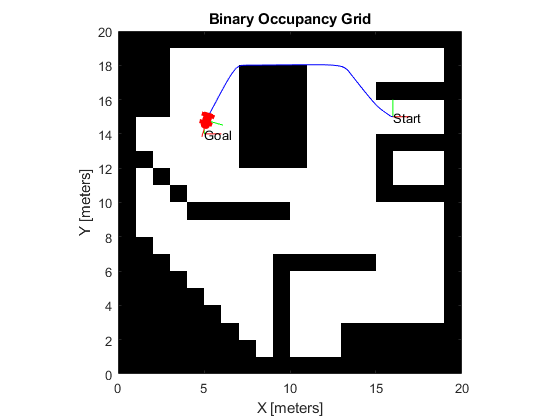

numRobots = size(robotPose, 2) / 3;
thetaIdx = 3;

% Translation
xyz = robotPose;
xyz(:, thetaIdx) = 0;

% Rotation in XYZ euler angles
theta = robotPose(:,thetaIdx);
thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
thetaEuler(:, end) = theta;

show(map)
hold on;

% Plot Start Location
plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
text(startLoc(1), startLoc(2), 2, 'Start');

% Plot Goal Location
plotTransforms([goalLoc, 0], eul2quat([0, 0, 0]))
text(goalLoc(1), goalLoc(2), 2, 'Goal');

% Plot Robot's XY locations
plot(robotPose(:, 1), robotPose(:, 2), '-b')

% Plot Robot's pose as it traverses the path
quat = eul2quat(thetaEuler(size(xyz, 1), :), 'xyz');
plotTransforms(xyz(size(xyz, 1),:), quat, 'MeshFilePath',...
    'groundvehicle.stl');

pause(0.01)
hold off;

view([0 90])

© Copyright 2019 The MathWorks, Inc.